clear all, close all, clc

############### ############### ############### ############### 

## Prob-01

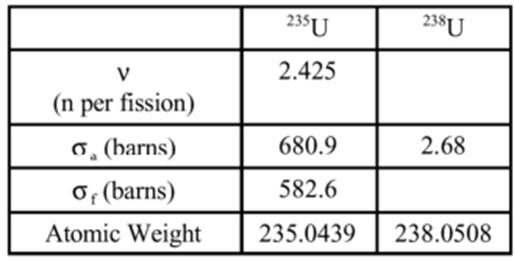

Let 1 for U-235, and 2 for U-238

Given,

rh = 18.9;          % ; g/cm^3
Na = 6.02e23;       % avogadro's; #
nu = 2.425;         % n/fissn

sg_a1 = 680.9;      % ; absorption CS; b
sg_a2 = 2.68;       % ; b
sg_f1 = 582.6;      % ; fission CS; b
A1 = 235.044;       % atomic weight; g/mol
A2 = 238.05;        %

We know,

$f_{\mathrm{ai}} =\frac{f_{\mathrm{wi}} /A_i }{\sum_i \;f_{\mathrm{wi}} /A_i }$        $f_{\textrm{ai}} =$ atomic fraction; $f_{\textrm{wi}} =$ weight fraction

Then we have, for atomic fraction

f1 = linspace(0.007, 1, 100);   % enrichment, U-235
f2 = 1 - f1;                    % weight fraction; U-238

% sm = f1/A1 + f2/A2;
% fa1 = f1/A1 ./sm;           % atomic fractin, U-235
% fa2 = 1 - fa1;              % U-238

N1 = f1 *rh*Na/A1;          % atomic density, U-235; #/cm^3
N2 = f2 *rh*Na/A2;

So, let's find the ratio, Here, 

$N=\;\frac{{\rho N}_a }{\sum_i \frac{f_{\mathrm{wi}} \;}{A_i }}\;$         N = atomic density; $f_{\textrm{wi}} =$ weight fraction/ enrichment

% N = rh*Na ./sm;             % atomic density; #/cm^3
Sg_a1 = N1 *sg_a1;
Sg_a2 = N2 *sg_a2;

Sg_a = Sg_a1 + Sg_a2;       % total macro a-CS of mixture

N = N1 +N2;                 % total density
Sg_f = N1 *sg_f1;      % macro' f-CS

Then let's find the ratio-


$$r=\frac{\nu \;\Sigma_f \;}{\Sigma_a }=\frac{\nu \;\Sigma_f \;}{\Sigma_{\textrm{a1}} +\Sigma_{\textrm{a2}} }$$
 

r = nu *Sg_f ./ Sg_a;

Now, let's plot them-

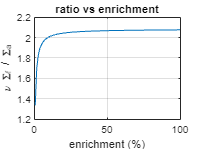

plot(f1*100, r), grid on
xlabel('enrichment (%)')
ylabel('\nu \Sigma_f / \Sigma_a')
title('ratio vs enrichment')

############### ############### ############### ############### 

## Prob-02

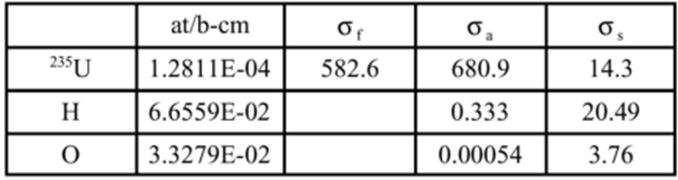

Given,

N_u = 1.2811e-4;        % atomic density; #/b-cm
N_h = 6.559e-2;
N_o = 3.3279e-2;

sg_f_u = 582.6;         % fission CS; b

sg_a_u = 680.9;         % absorption CS; b
sg_a_h = 0.333;
sg_a_o = 5.4e-4;

sg_s_u = 14.3;          % scattering CS; b
sg_s_h = 20.49;
sg_s_o = 3.76;          

So, we have-

$\Sigma_s =\sum_{\;} N_i \;\sigma_{\textrm{si}} \;$         $\Sigma_s =$ macroscopic CS

Sg_s = (N_u *sg_s_u + N_h *sg_s_h + N_o *sg_s_o)  % macro' absorption CS; 1/cm

Sg_s = 1.4709

Then, $\lambda =\frac{1}{\Sigma_s }$

lm = 1 /Sg_s            % mean free path; cm

lm = 0.6799

Now, mean chord length


$$\bar{c} =\frac{4}{3}R$$


R = 14.2;               % sphere radius; cm
c = 4/3 *R              % mean chord length

c = 18.9333

As, MFP is much smaller than mean chord length. It means the neutron undergoes a lot of scattering within the system. Which makes the thermalization probability higher.

############## ############### ############### ############### 

## Prob-03

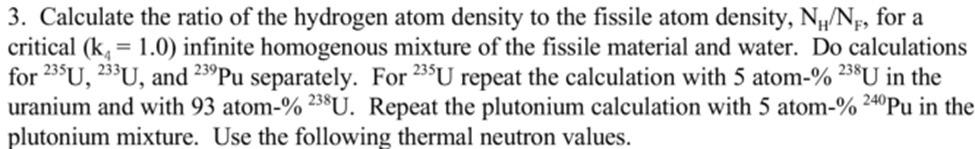

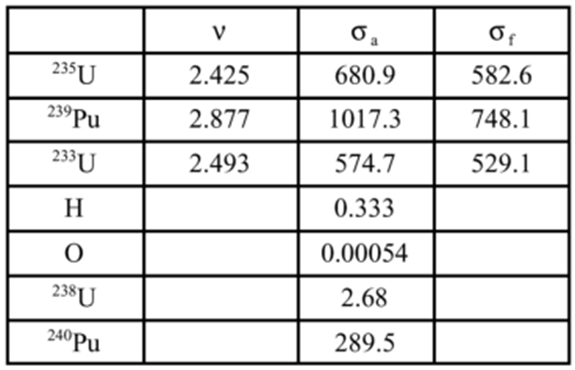

Here, for $k_e =1$, we have

$k_e =\frac{\nu \;\Sigma_f \;}{\Sigma_a }$         sub, a for absorption, f for fissile (U, Pu)

as, $\Sigma_a =N_f \sigma_{\textrm{af}} +N_h \sigma_{\textrm{ah}} \;$

and, $\Sigma_f =N_f \sigma_f$ 

This leads to the follows-


$$\frac{N_h }{N_f }=\frac{\nu \;\sigma_f -\sigma_{\mathrm{af}} \;\;}{\sigma_{\mathrm{ah}} \;}$$


Let, u1 = U-235, u2 = U-233, u3 = U-238;  p1 = Pu-239; p2 = Pu-240

Now given,

nu_u1 = 2.425;          % n/fsn;
nu_u2 = 2.493;
nu_p1 = 2.877;

sg_a_u1 = 680.9;        % abs' CS; b
sg_a_u2 = 574.7;
sg_a_p1 = 1017.3;
sg_a_u3 = 2.68;
sg_a_p2 = 289.5;

sg_a_h = 0.333;

sg_f_u1 = 582.6;        % fission CS; b
sg_f_u2 = 529.1;
sg_f_p1 = 748.1;

Now, let's calcualte hydrogen to fissile atom density ratio


$$r_{\textrm{hf}} =\frac{N_h }{N_f }=\frac{\nu \;\sigma_f -\sigma_{\textrm{af}} \;\;}{\sigma_{\textrm{ah}} \;}$$


r_h_u1 = (nu_u1 *sg_f_u1 - sg_a_u1) /sg_a_h         % for U-235

r_h_u1 = 2.1979e+03

r_h_u2 = (nu_u2 *sg_f_u2 - sg_a_u2) /sg_a_h         % for U-233

r_h_u2 = 2.2353e+03

r_h_p1 = (nu_p1 *sg_f_p1 - sg_a_p1) /sg_a_h         % for U-233

r_h_p1 = 3.4084e+03

For mixtures

f1 = 0.05;                   % 5% U-238% in U-235 
sg_a_ux1 = f1*sg_a_u3 + (1-f1)*sg_a_u1               % ; b

sg_a_ux1 = 646.9890

sg_f_ux1 = sg_f_u1 *(1-f1);                          % ; b
r_h_ux1 = (nu_u1 *sg_f_ux1 - sg_a_ux1) /sg_a_h     % 5% U-238

r_h_ux1 = 2.0876e+03

(Ans)

Then,

f2 = 0.93;                   % 93% U-238% in U-235 
sg_a_ux2 = f2*sg_a_u3 + (1-f2)*sg_a_u1              % ; b

sg_a_ux2 = 50.1554

sg_f_ux2 = sg_f_u1 *(1-f2);                         % ; b
r_h_ux2 = (nu_u1 *sg_f_ux2 - sg_a_ux2) /sg_a_h     % 93% U-238

r_h_ux2 = 146.3692

(Ans)

Lastly,

f1 = 0.05;                   % 5% U-238% in U-235 
sg_a_px1 = f1*sg_a_p2 + (1-f1)*sg_a_p1               % ; b

sg_a_px1 = 980.9100

sg_f_px1 = sg_f_p1 *(1-f1);                          % ; b
r_h_px1 = (nu_p1 *sg_f_px1 - sg_a_px1) /sg_a_h     % 5% Pu-240

r_h_px1 = 3.1945e+03

(Ans)

############## ############### ############### ############### 

## Prob-04

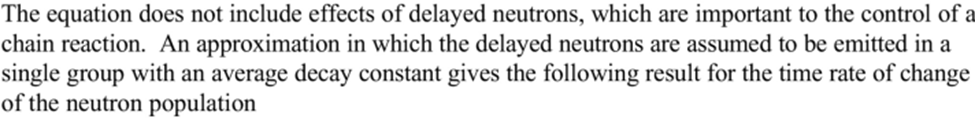

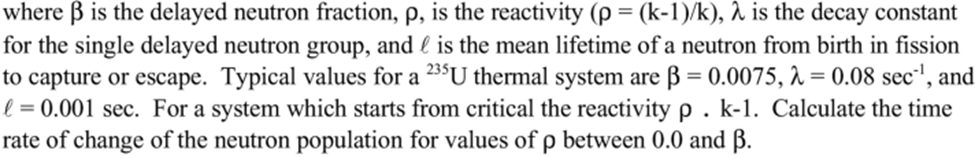

Given,

bt = 0.0075;                % delayed nu' fraction
lm = 0.08;                  % DN decay const; 1/s
l = 0.001;                  % DN lifetime; s
N_o = 1;                    % assumed

rh = linspace(0, bt, 11);   % reactivity
t = 2                       % time 

t = 2

t = linspace(0, 1, 11);     % time; s

Now, the equation of change for nu' population is-


$$N\left(t\right)=N_0 \;\left\lbrack \left(\frac{\beta \;}{\beta -\rho \;}\right)\;\exp \left(\frac{\lambda \rho \;\;}{\beta -\rho \;}\right)t\;-\left(\frac{\rho \;}{\beta -\rho \;}\right)\exp \left(-\frac{\beta -\rho \;\;\;}{l\;}\right)t\right\rbrack$$


So, the time rate be-


$$\frac{N\left(t\right)}{\textrm{dt}}=N_0 \;\left\lbrack \left(\frac{\beta \;}{\beta -\rho \;}\right)\;\left(\frac{\lambda \rho \;\;}{\beta -\rho \;}\right)\exp \left(\frac{\lambda \rho \;\;}{\beta -\rho \;}\right)t+\left(\frac{\rho \;}{\beta -\rho \;}\right)\left(\frac{\beta -\rho \;\;\;}{l\;}\right)\exp \left(-\frac{\beta -\rho \;\;\;}{l\;}\right)t\right\rbrack$$


Or, $\frac{N\left(t\right)}{\textrm{dt}}=N_0 \;\left\lbrack \left(\frac{\beta \lambda \rho \;}{{\left(\beta -\rho \right)}^2 \;}\right)\;\exp \left(\frac{\lambda \rho \;\;}{\beta -\rho \;}\right)t+\left(\frac{\rho \;}{l\;}\right)\exp \left(-\frac{\beta -\rho \;\;\;}{l\;}\right)t\right\rbrack$

Now, let's put it into code

    l1 = length(rh);
    l2 = length(t);
N_t = zeros(l1, l2);        % initialize

Now, let's make it into a loop

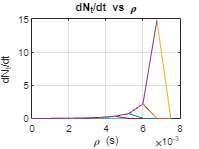

for i = 1:1:length(rh)
    for j = 1:1:length(t)
         T1 = bt*lm .*rh(i) /(bt -rh(i)).^2 .*exp(lm.*rh(i) /(bt -rh(i)) .*t(j));    % term-1
         T2 = rh(i) .*l .*exp((rh(i) - bt)/l .*t(j));
        N_t(i, j) = N_o *(T1 + T2);   
    end
    plot(rh, N_t(:,j)), grid on, hold on
    xlabel('\rho (s)'); ylabel('dN_t/dt')
    title('dN_t/dt vs \rho')
end

So, the above plot shows various $\frac{{\textrm{dN}}_t }{\textrm{dt}}\;$values at different $\rho \;$for different times. 

############## ############### ############### ############### 

## Crit Safety Problems

## Prob-01

Given,

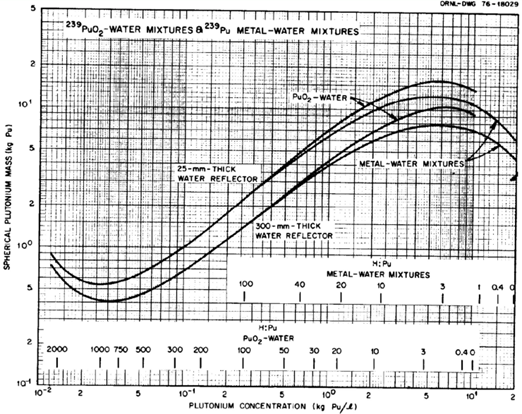

The extracted values are given in the following table.

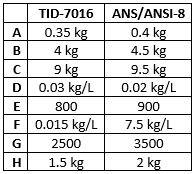

############## ############### ############### ############### 

## Chapter 06

## Prob-04

Validation is necessary for ensuring evaluation of models, whether it accurately predicts nuclear criticality safety condition.

It verifies the reliability of model, correct biases, and establish its reliability as they’re compared with the experimental results. 

The process itself consists: comparison with experiment > statistical evaluation > bias correction > validation of cross section > reconfirmation

############## ############### ############### ############### 

## Prob-11

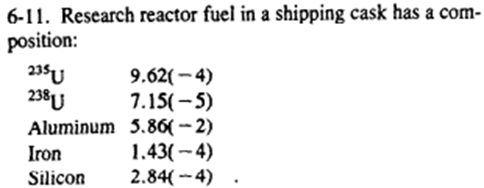

Assuming the composition is given in gm, and u1 for u-235, u2 for u-238

m_u1 = 9.62e-4;     % mass, u-235; g
m_u2 = 7.15e-5;
m_al = 5.86e-2;
m_i = 1.43e-4;
m_si = 2.84e-4;

m_T = m_u1 +m_u2 +m_al +m_i +m_si ;     % total mass; g

So, let's find the weight percentage 

f_w_u1 = m_u1/m_T *100      % weight fraction, u-235; %

f_w_u1 = 1.6017

f_w_u2 = m_u2/m_T *100

f_w_u2 = 0.1190

f_w_al = m_al/m_T *100

f_w_al = 97.5683

f_w_i  = m_i/m_T  *100

f_w_i = 0.2381

f_w_si = m_si/m_T *100

f_w_si = 0.4729

(Ans)

We know,

Na = 6.02e23;       % Avogadro's no.
A_u1 = 235;         % mas no.; g/mol
A_u2 = 238;
A_al = 27;
A_i = 56;
A_si = 28;

And the densities are-

rh_u1 = 19.1;        % u-235; g/cm^3
rh_u2 = 19.05;
rh_al = 2.7;
rh_i = 7.87;
rh_si = 2.33;

Now, it's 

$N_i =\frac{\rho_i \;N_a }{A_i }$        $N_i =$ number density

Let's find the atomic density of each composition-

N_u1 = rh_u1*Na /A_u1       % number density, u-235; #/cm^3

N_u1 = 4.8929e+22

N_u2 = rh_u2*Na /A_u2

N_u2 = 4.8185e+22

N_al = rh_al*Na /A_al

N_al = 6.0200e+22

N_i  = rh_i*Na  /A_i

N_i = 8.4603e+22

N_si = rh_si*Na /A_si

N_si = 5.0095e+22

So, no. density of the entire pellet would be-

N_T = N_u1 + N_u2 + N_al + N_i + N_si

N_T = 2.9201e+23

(Ans)

############## ############### ############### ############### 

## Prob-12

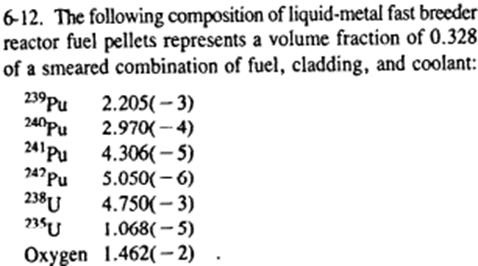

Given,

p1 = pu-239, p2 = Pu-240, p3 = Pu-241, p4 = Pu-242

u1 = U-235, u2 = U-238 

Given,

m_p1 = 2.205e-3;      % composition
m_p2 = 2.970e-4;
m_p3 = 4.306e-5;
m_p4 = 5.050e-6;
m_u2 = 4.750e-3;
m_u1 = 1.068e-5;
m_o = 1.462e-2;

m_T = m_p1 + m_p2 + m_p3 + m_p4 + m_u1 + m_u2 + m_o

m_T = 0.0219

(Ans)

So, let's find the mass fraction

f_w_p1 = m_p1 /m_T *100

f_w_p1 = 10.0544

f_w_p2 = m_p2 /m_T *100

f_w_p2 = 1.3543

f_w_p3 = m_p3 /m_T *100

f_w_p3 = 0.1963

f_w_p4 = m_p4 /m_T *100

f_w_p4 = 0.0230

f_w_u1 = m_u1 /m_T *100

f_w_u1 = 0.0487

f_w_u2 = m_u2 /m_T *100

f_w_u2 = 21.6590

f_w_o  = m_o  /m_T *100

f_w_o = 66.6643

Now, we know

Na = 6.023e23;      % Avogadro's number

A_p1 = 239;         % molar mass, Pu-239
A_p2 = 240;
A_p3 = 241;
A_p4 = 242;
A_u1 = 235;
A_u2 = 238;
A_o = 16;

And the densities

rh_p1 = 19.85;      % density, pu-239; g/cm^3
rh_p2 = 19.8;
rh_p3 = 19.85

rh_p3 = 19.8500

rh_p4 = 19.85;
rh_u1 = 19.1;
rh_u2 = 19.05;
rh_o = 1.42e-3;

Then,


$$N_i =\frac{\rho_i \;N_a }{A_i }$$


Let's find the number density-

N_p1 = rh_p1 *Na /A_p1      % no. density, pu-239; #/cm^3

N_p1 = 5.0024e+22

N_p2 = rh_p2 *Na /A_p2

N_p2 = 4.9690e+22

N_p3 = rh_p3 *Na /A_p3

N_p3 = 4.9609e+22

N_p4 = rh_p4 *Na /A_p4

N_p4 = 4.9404e+22

N_u1 = rh_u1 *Na /A_u1

N_u1 = 4.8953e+22

N_u2 = rh_u2 *Na /A_u2

N_u2 = 4.8209e+22

N_o  = rh_o  *Na /A_o

N_o = 5.3454e+19

(Ans)